# Q1:

questions.q1 = 8/20;
display(questions.q1)

    0.4000



## Q2:

questions.q2 = (12/20)*(12/20); 
display(questions.q2)

    0.3600



## Q3:

questions.q3 = nchoosek(20,8)*(8/20)^8*(12/20)^(20-8); 
display(questions.q3)

    0.1797



## Q4:

questions.q4 = 1 - (nchoosek(20,8)*(8/20)^8*(12/20)^(20-8)); 

display(questions.q4)

    0.8203



## Q5:

questions.q5a = 1 - binocdf(8, 20, (8/20)); 
display(questions.q5a)

    0.4044



## Q6:

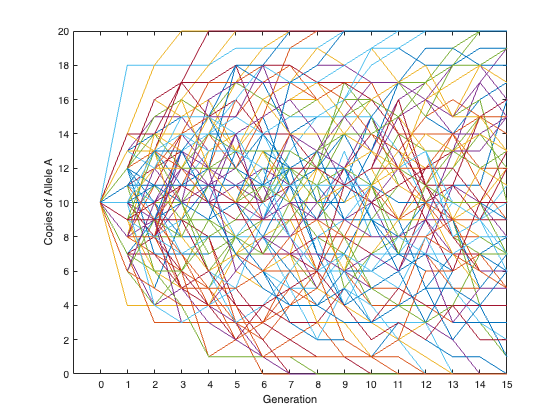

figure;
chains = sim_wright_fisher(20, 10, 15, 100);

p = plot(chains);
xticks(1:16)
xticklabels(cellstr(num2str((0:15)')))
xlabel("Generation")
ylabel("Copies of Allele A")

## Q7:

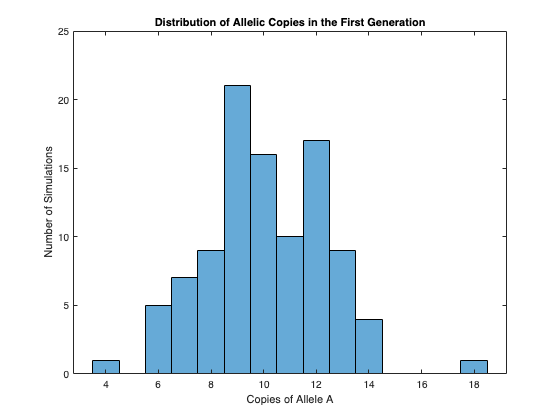

figure;
h = histogram(chains(2,:));
title("Distribution of Allelic Copies in the First Generation")
xlabel("Copies of Allele A")
ylabel("Number of Simulations")

## Q8:

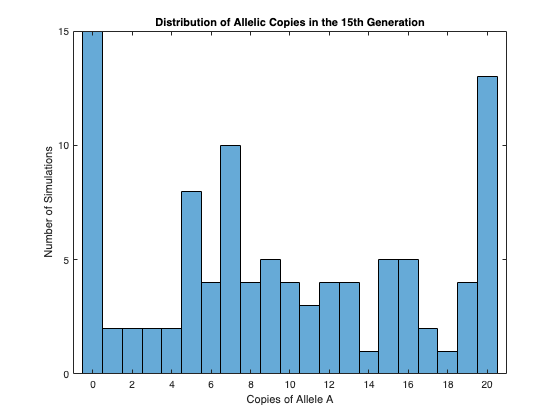

figure;
h = histogram(chains(16,:));
title("Distribution of Allelic Copies in the 15th Generation")
xlabel("Copies of Allele A")
xlim([-1 21])
ylabel("Number of Simulations")

n_fixed = sum(h.BinCounts([1, 21]));

questions.q8 = n_fixed;
display(questions.q8)

    28



## Q9a:

N = 10;
P = zeros(2*N+1, 2*N+1);

for i = 0:2*N
    P(i+1,:) = binopdf(0:2*N, 2*N, i/(2*N));
end

display(P)

P =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.3585    0.3774    0.1887    0.0596    0.0133    0.0022    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1216    0.2702    0.2852    0.1901    0.0898    0.0319    0.0089    0.0020    0.0004    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0388    0.1368    0.2293    0.2428    0.1821    0.1028    0.0454    0.0160    0.0046    0.0011    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0115    0.0576    0.1369    0.2054    0.2182    0.1746    0.1091    0.0545    0.0222    0.0074    0.0020    0.0005    0.0001    0.0000    0.0000  

## Q9b:

pi0 = zeros(1, 2*N+1);
pi0(N+1) = 1;

questions.q9b = pi0;
display(questions.q9b)

     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0



## Q9c:

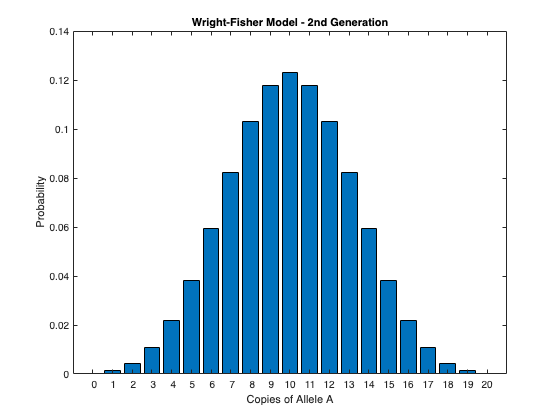

figure;
pi2 = pi0*P^2; 
b = bar(pi2);
xlim([0 22])
xticks(1:21)
xticklabels(cellstr(num2str((0:20)')))
xlabel("Copies of Allele A")
ylabel("Probability")
title("Wright-Fisher Model - 2nd Generation")

## Q9d:

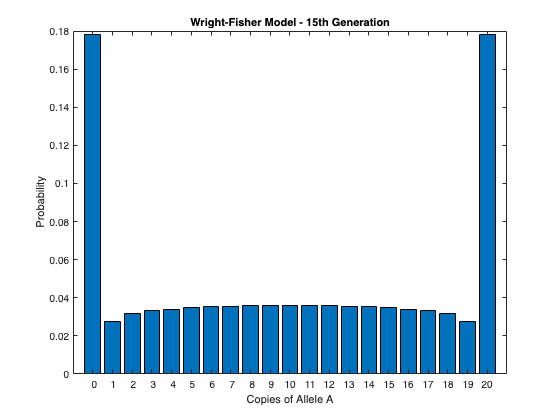

figure;
pi15 = pi0*P^15; 
b = bar(pi15);
xlim([0 22])
xticks(1:21)
xticklabels(cellstr(num2str((0:20)')))
xlabel("Copies of Allele A")
ylabel("Probability")
title("Wright-Fisher Model - 15th Generation")

## Q10:

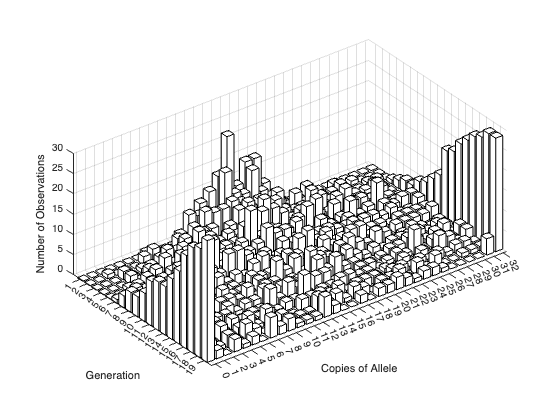

figure;
buri_data = csvread('buri_data.csv');
bar3(buri_data(2:end,:), 'w')
xlabel("Copies of Allele")
yticks(1:length(buri_data(:,1))-1)
xticks(1:33)
xticklabels(cellstr(num2str((0:32)')))
ylabel("Generation")
zlabel("Number of Observations")

## Q11:

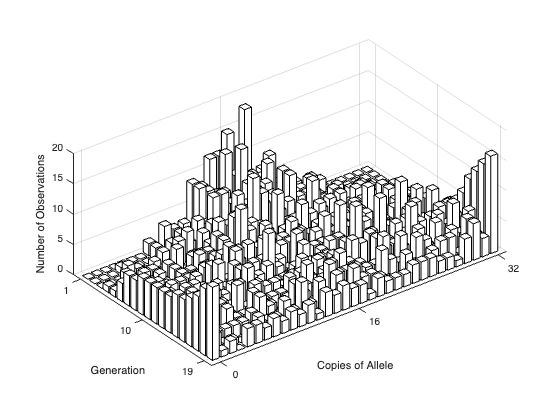

N_sim = 107;
N_genes = 32;
N_copies_initial = 16; 
N_generations = 19; 

[chains, counts] = sim_wright_fisher(N_genes, N_copies_initial, N_generations, N_sim); 

bar3(counts(2:end,:), "white")
xlim([0, N_genes+2]);
xlabel('Copies of Allele')
yticks([1, 10, 19])
xticks([1, 17, 33]);
xticklabels(cellstr(num2str(([0, 16, 32])')))
ylabel("Generation")
zlabel("Number of Observations")